# Plot Group Means and Confidence Intervals for Matrix Input

Plot group means and confidence intervals for input data in a matrix. Group the input data using one or two grouping variables, and specify one or two variables for which you want to plot the summary statistics.

Load the `carsmall` data set, which contains measurements of 100 cars.

load carsmall

The variable `Acceleration` is the time from 0 to 60 MPH in seconds. The grouping variable `Cylinders` is the number of cylinders in each car.

Plot the mean acceleration grouped by cylinder, with 95% confidence intervals.

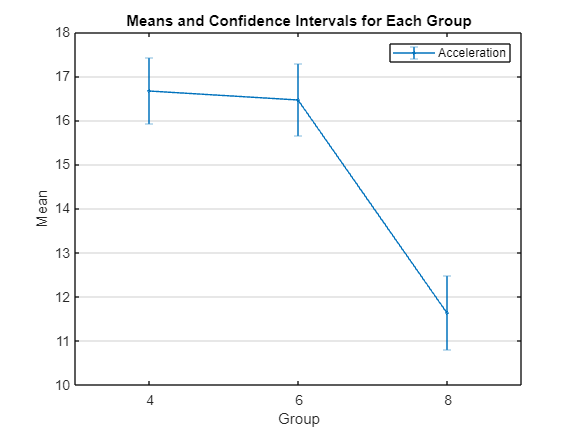

grpstats(Acceleration,Cylinders,0.05);
legend("Acceleration")

The mean acceleration for cars with 8 cylinders is significantly lower than for cars with 4 or 6 cylinders. 

The variable `Weight` is the weight value for each car. Plot the mean acceleration and weight grouped by cylinder, with 95% confidence intervals. Scale the `Weight` values by 1000 so the means of `Weight` and `Acceleration` are the same order of magnitude.

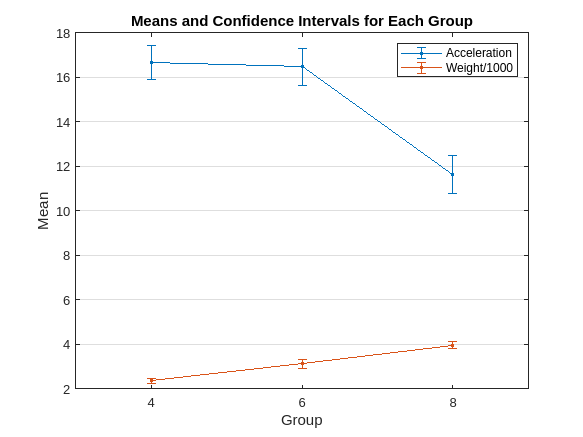

grpstats([Acceleration,Weight/1000],Cylinders,0.05);
legend("Acceleration","Weight/1000")

The mean weight of cars increases with the number of cylinders, and the mean acceleration decreases with the number of cylinders.

The `Model_Year` variable has three unique values, 70, 76, and 82, which correspond to the model years 1970, 1976, and 1982. Plot the mean acceleration grouped by both cylinder and model year. Specify 95% confidence intervals. 

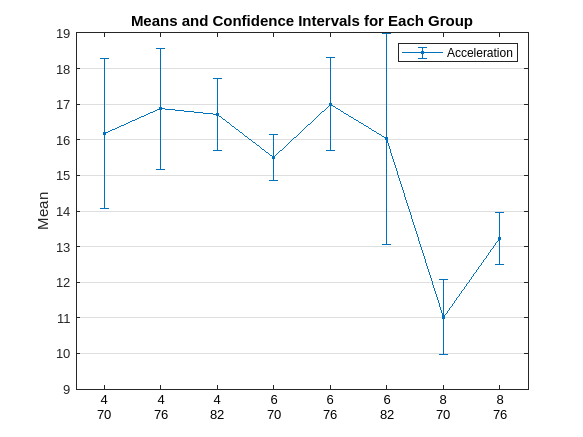

grpstats(Acceleration,{Cylinders,Model_Year},0.05);
legend("Acceleration")

The two grouping variables `Cylinders` and `Model_Year` have nine possible combinations of values, because each variable has three unique values. The plot does not show 8-cylinder cars with the model year 1982 because the data does not include this combination.

The mean acceleration of 8-cylinder cars made in 1976 is significantly larger than the mean acceleration of 8-cylinder cars made in 1970. 

*Copyright 2012 The MathWorks, Inc.*